Ввод количества индивидуумов, интервала дискретизации в популяции и число поколений. Задание передаточной функции.


DeltaSize = 0.001;   % интервал дискретизации

SizePopulation = 30;

MaxGen = 15;
s = tf('s');      % символическое задание оператора Лапласа
G = 1 / (s * (s * s + s + 1));    % передаточная функция объекта управления

Задание оптимальных значений параметров регулятора и вызов функции ga()

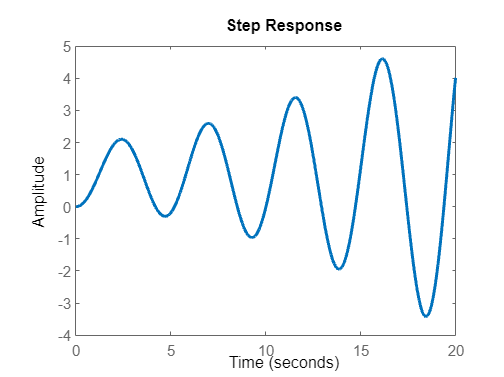

Optimization terminated: maximum number of generations exceeded.


options = optimoptions(@ga,'PopulationSize',SizePopulation,'MaxGenerations',MaxGen,'OutputFcn',@history_func);
[x,fval] = ga(@(K)PID_func(G,DeltaSize,K),3,-eye(3),zeros(3,1),[],[],[],[],[],options);

Построение грфиков переходных процессов, управления, значения функционала, переходных процессов

MinJIndex = zeros(1, size(data.cost, 2));

for i = 1 : size(data.cost, 2)

    
    MinJIndex(i) = min(find(data.cost(:, i) == min(data.cost(:, i))));
end

figure()
for i = 1 : size(data.cost, 2)
    [y, u, t, ClosedLoop] = plotting(G,DeltaSize,data.history(MinJIndex(i), :, i));

    plot(t, y)

    ylim([-3 3])

    xlabel('t')
    
    ylabel('y')

    grid on
    title('График переходные процессы для лучших представителей')
    hold on
end

figure()
for i = 1 : size(data.cost, 2)
    [y, u, t, ClosedLoop] = plotting(G,DeltaSize,data.history(MinJIndex(i), :, i));
    plot(t, u)
    ylim([-3 3])

    xlabel('t')

    ylabel('u')

    grid on
    title('График управление для лучших представителей')
    hold on
end

figure()
for i = 1 : size(data.cost, 2)
    [y, u, t, ClosedLoop] = plotting(G,DeltaSize,data.history(MinJIndex(i), :, i));
    plot(t, step(ClosedLoop,t))
    ylim([-3 3])

    xlabel('t')

    ylabel('J')

    grid on
    title('График поведение функционала для лучших представителей')
    hold on
end

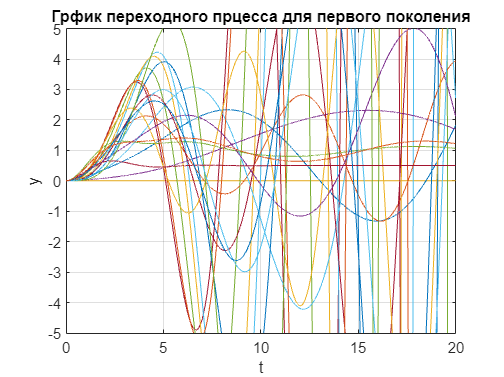

data = load('history.mat', 'cost', 'history');

figure()
for i = 1 : size(data.cost, 1)
    [y, u, t, ClosedLoop] = plotting(G,DeltaSize,data.history(i, :, 1));

    plot(t, y)
    
    ylabel('y')

    ylim([-5 5])

    xlabel('t')
    grid on
    title('Грфик переходного прцесса для первого поколения')
    hold on
end

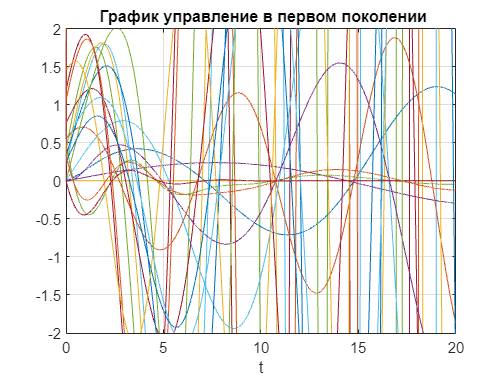

figure()
for i = 1 : size(data.cost, 1)

    [y, u, t, ClosedLoop] = plotting(G,DeltaSize,data.history(i, :, 1));

    plot(t, u)

    ylim([-2 2])
    
    xlabel('t')

    grid on
    
    title(' График управление в первом поколении')
    hold on
end

figure()
for i = 1 : size(data.cost, 1)
    [y, u, t, ClosedLoop] = plotting(G,DeltaSize,data.history(i, :, 1));
    plot(t, step(ClosedLoop,t))
    ylim([-1 3])

    xlabel('t')

    ylabel('J')

    grid on
    title('График значение функционала в первом поколении')
    hold on
end

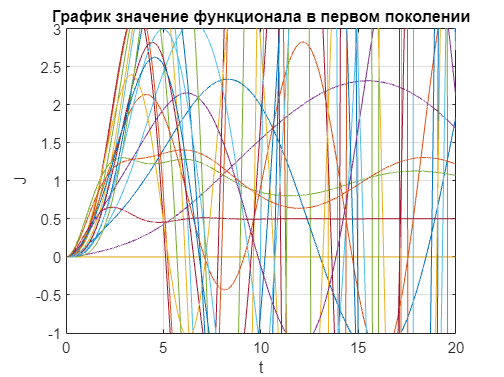

figure()

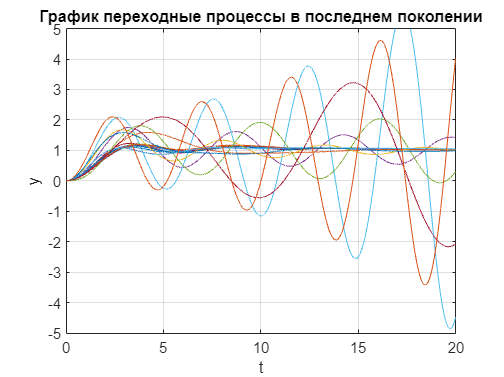

for i = 1 : size(data.cost, 1)
    [y, u, t, ClosedLoop] = plotting(G,DeltaSize,data.history(i, :, 16));
    plot(t, y)
    ylim([-5 5])

    xlabel('t')

    ylabel('y')

    grid on
    title('График переходные процессы в последнем поколении')
    hold on
end
figure()
for i = 1 : size(data.cost, 1)

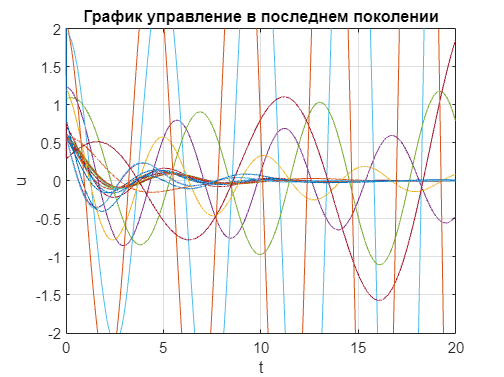

    [y, u, t, ClosedLoop] = plotting(G,DeltaSize,data.history(i, :, 16));
    plot(t, u)
    ylim([-2 2])

    xlabel('t')

    ylabel('u')

    grid on
    title('График управление в последнем поколении')
    hold on
end
figure()
for i = 1 : size(data.cost, 1)

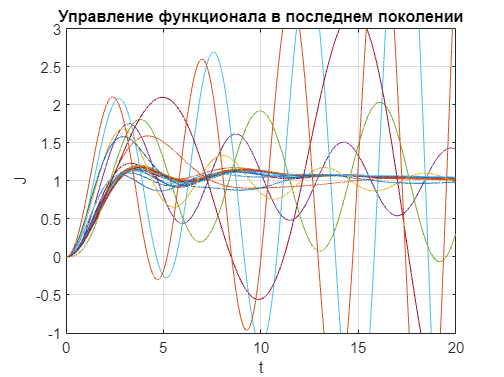

    [y, u, t, ClosedLoop] = plotting(G,DeltaSize,data.history(i, :, 16));
    plot(t, step(ClosedLoop,t))
    ylim([-1 3])

    xlabel('t')

    ylabel('J')

    grid on
    title('График правление функционала в последнем поколении')
    hold on
end
